# 3.6 Анализ данных

**Практическое занятие**

## Загрузка данных

Загрузите из файла `data.mat` переменную `S`. Это записанный во время лабораторной работы сигнал во времени (подсказка: `load`)

load data S

## Обработка сигнала

Найдите количество пропущенных значений в сигнале (подсказка: `ismissing()`, `nnz()`)

nnz(ismissing(S.Signal))

ans = 44

Замените пропущенные значения методом линейной интерполяции (`linear`). Результат запишите в новый столбец `Signal2` (подсказка: `fillmissing()`)

S.Signal2 = fillmissing(S.Signal, 'linear')

S = 1001×3 table
            Time             Signal     Signal2 
    ____________________    ________    ________

    12-Sep-2018 12:52:00     0.73767     0.73767
    12-Sep-2018 12:52:00       2.043       2.043
    12-Sep-2018 12:52:00     -2.0406     -2.0406
    12-Sep-2018 12:52:00      1.0895      1.0895
    12-Sep-2018 12:52:00     0.55516     0.55516
    12-Sep-2018 12:52:00     -1.0622     -1.0622
    12-Sep-2018 12:52:00    -0.17901    -0.17901
    12-Sep-2018 12:52:00      0.6063      0.6063
    12-Sep-2018 12:52:00      3.8512      3.8512
    12-Sep-2018 12:52:00      3.0513      3.0513
    12-Sep-2018 12:52:01      -1.059      -1.059
    12-Sep-2018 12:52:01      3.3349      3.3349
    12-Sep-2018 12:52:01      1.0345      1.0345
    12-Sep-2018 12:52:01     0.25508     0.25508
    12-Sep-2018 12:52:01      1.0419      1.0419
    12-Sep-2018 12:52:01     0.13128     0.1312

Сгладьте сигнал `Signal2` методом скользящего среднего по `50` точкам

S.Signal2 = movmean(S.Signal2, 50)

S = 1001×3 table
            Time             Signal     Signal2
    ____________________    ________    _______

    12-Sep-2018 12:52:00     0.73767    0.93262
    12-Sep-2018 12:52:00       2.043    0.95294
    12-Sep-2018 12:52:00     -2.0406    0.96069
    12-Sep-2018 12:52:00      1.0895    0.93141
    12-Sep-2018 12:52:00     0.55516    0.92505
    12-Sep-2018 12:52:00     -1.0622    0.88338
    12-Sep-2018 12:52:00    -0.17901    0.89873
    12-Sep-2018 12:52:00      0.6063     0.8498
    12-Sep-2018 12:52:00      3.8512    0.80647
    12-Sep-2018 12:52:00      3.0513    0.77358
    12-Sep-2018 12:52:01      -1.059    0.68182
    12-Sep-2018 12:52:01      3.3349    0.71715
    12-Sep-2018 12:52:01      1.0345    0.72072
    12-Sep-2018 12:52:01     0.25508    0.69592
    12-Sep-2018 12:52:01      1.0419     0.7271
    12-Sep-2018 12:52:01     0.13128     0.6799


При измерении из-за погрешности сигнал был смещен на некоторую величину относительно нуля. Приведите среднее значение сигнала `Signal2` к нулю. результат запишите в новый столбец `Signal3` (подсказка: `mean()`)

S.Signal3 = S.Signal2 - mean(S.Signal2)

S = 1001×4 table
            Time             Signal     Signal2    Signal3
    ____________________    ________    _______    _______

    12-Sep-2018 12:52:00     0.73767    0.93262    0.70071
    12-Sep-2018 12:52:00       2.043    0.95294    0.72103
    12-Sep-2018 12:52:00     -2.0406    0.96069    0.72878
    12-Sep-2018 12:52:00      1.0895    0.93141     0.6995
    12-Sep-2018 12:52:00     0.55516    0.92505    0.69314
    12-Sep-2018 12:52:00     -1.0622    0.88338    0.65147
    12-Sep-2018 12:52:00    -0.17901    0.89873    0.66682
    12-Sep-2018 12:52:00      0.6063     0.8498    0.61789
    12-Sep-2018 12:52:00      3.8512    0.80647    0.57456
    12-Sep-2018 12:52:00      3.0513    0.77358    0.54167
    12-Sep-2018 12:52:01      -1.059    0.68182    0.44991
    12-Sep-2018 12:52:01      3.3349    0.71715    0.48524
    12-Sep-2018 12:5

Отобразите все 3 сигнала на одном графике (подсказка: `plot()`)

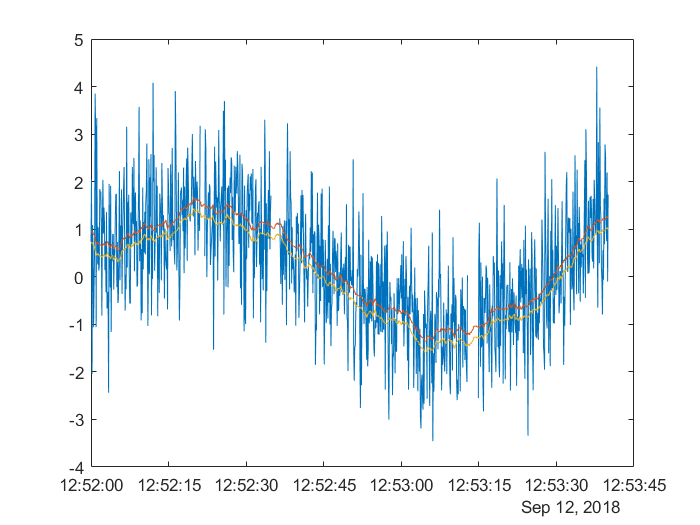

plot(S.Time, S{:, 2:end})

## Анализ сигнала

Определите разброс и стандартное отклонение сигнала `Signal3` (подсказка: `std()`)

std(S.Signal3)

ans = 0.9088

По форме сигнал `Signal3` похож на синусоиду. Найдите её амплитуду (подсказка: `max(), min()`)

(max(S.Signal3) - min(S.Signal3)) / 2

ans = 1.5133